## MINI PROJECT

### VISUAL AID TEXT IMAGE TO AUDIO FOR  BLIND PEOPLE

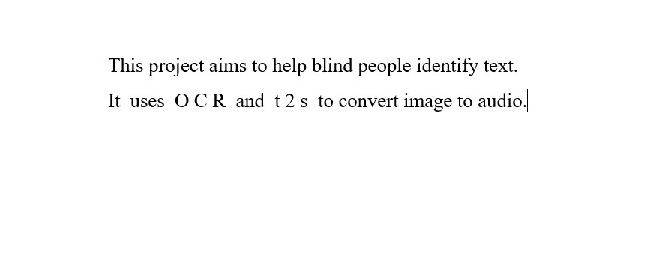

% Step 1: Load Image
imageFile = 'img1.jpg'; % Replace with your image file
img = imread(imageFile);
imshow(img)

% Step 2: Preprocessing
grayImage = rgb2gray(img);  % Convert RGB to grayscale
bwImage = imbinarize(grayImage, 'adaptive', 'ForegroundPolarity', 'dark', 'Sensitivity', 0.4); % Adjust sensitivity

% Step 3: OCR (Optical Character Recognition)
ocrResults = ocr(bwImage);  % Perform OCR on the binary image
recognizedText = ocrResults.Text;  % Extract recognized text

% Step 4: Display Recognized Text
disp(recognizedText);

This project aims to help blind people identify text.

It uses OCR and t2s to convert image to audio.





% Step 5: Text-to-Speech Conversion
recognizedText = char(recognizedText); % Convert from cell to string.
NET.addAssembly('System.Speech');
obj = System.Speech.Synthesis.SpeechSynthesizer;
obj.Volume = 100;
outputFileName = 'audio.wav';
obj.SetOutputToWaveFile(outputFileName);
obj.Speak(recognizedText);
obj.SetOutputToDefaultAudioDevice();
disp(['Audio saved to ', outputFileName]);

Audio saved to audio.wav


[](https://www.ieee.org/conferences/publishing/templates.html)